clear all
close all
clc

theta2 = sym('theta_2')

$$theta2 = \theta_{2}$$

theta3 = sym('theta_3')

$$theta3 = \theta_{3}$$

theta4 = sym('theta_4')

$$theta4 = \theta_{4}$$

l1 = 90; 
l2 = 30; 
l3 = 75; 
l4 = 75; 
BP=75;
O2x=0; O2y=0;
O4x=l1; O4y=0;

### **Equation of Motions**

Ax = l2*cos(theta2);
Ay = l2*sin(theta2);
Bx = O4x-l4*cos(theta4);
By = O4y+l4*sin(theta4);

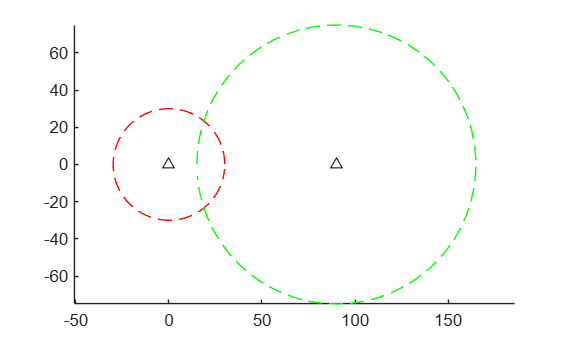

figure()
hold on
plot(O2x,O2y,"^k")
plot(O4x,O4y,"^k")
plot(subs(Ax,0:0.1:2*pi),subs(Ay,0:0.1:2*pi),"--r")
plot(subs(Bx,0:0.1:2*pi),subs(By,0:0.1:2*pi),"--g")
hold off
axis equal

eq1 = Bx == Ax+l3*cos(theta3);
eq2 = By == Ay+l3*sin(theta3);

sol = solve([eq1 eq2],[theta3 theta4]);

theta3_sol = sol.theta_3(1);
theta4_sol = sol.theta_4(1);
d = sqrt((O4x-Ax)^2+(O4y-Ay)^2);
theta3_sol = atan2(O4y-Ay,O4x-Ax)+acos((l3^2+d^2-l4^2)/(2*l3*d)); 
theta4_sol = atan2(Ay+l3*sin(theta3_sol)-O4y,O4x-Ax-l3*cos(theta3_sol));

gamma1 = 72;
AP = 2*l3*cos(deg2rad(90-0.5*gamma1));
Px1 = Ax+AP*cos(theta3_sol+deg2rad(90-0.5*gamma1)); 
Py1 = Ay+AP*sin(theta3_sol+deg2rad(90-0.5*gamma1));

gamma2 = 180;
AP2 = 2*l3*cos(deg2rad(90-0.5*gamma2));
Px2 = Ax+AP2*cos(theta3_sol+deg2rad(90-0.5*gamma2)); 
Py2 = Ay+AP2*sin(theta3_sol+deg2rad(90-0.5*gamma2));

gamma3 = 216;
AP3 = 2*l3*cos(deg2rad(90-0.5*gamma3));
Px3 = Ax+AP3*cos(theta3_sol+deg2rad(90-0.5*gamma3)); 
Py3 = Ay+AP3*sin(theta3_sol+deg2rad(90-0.5*gamma3));

BxNew = subs(Bx,theta4,theta4_sol);
ByNew = subs(By,theta4,theta4_sol);

omega2 = 1; 
q = linspace(0,2*pi,361); 
theta2Deg = rad2deg(q);

positionP = [Px1; Py1; Px2; Py2; Px3; Py3];


positionP = double(subs(positionP,theta2,q)); 


syncFigure = uifigure('Name','Four-bar linkage and crank-angle plots','WindowState','maximized','HandleVisibility','on');
windowLayout = uigridlayout(syncFigure,[2 1]);
windowLayout.RowHeight = {32,'1x'};
replayButton = uibutton(windowLayout,'Text','Replay','Enable','off');
plotPanel = uipanel(windowLayout,'BorderType','none');
syncLayout = tiledlayout(plotPanel,3,2,'TileSpacing','compact','Padding','compact');

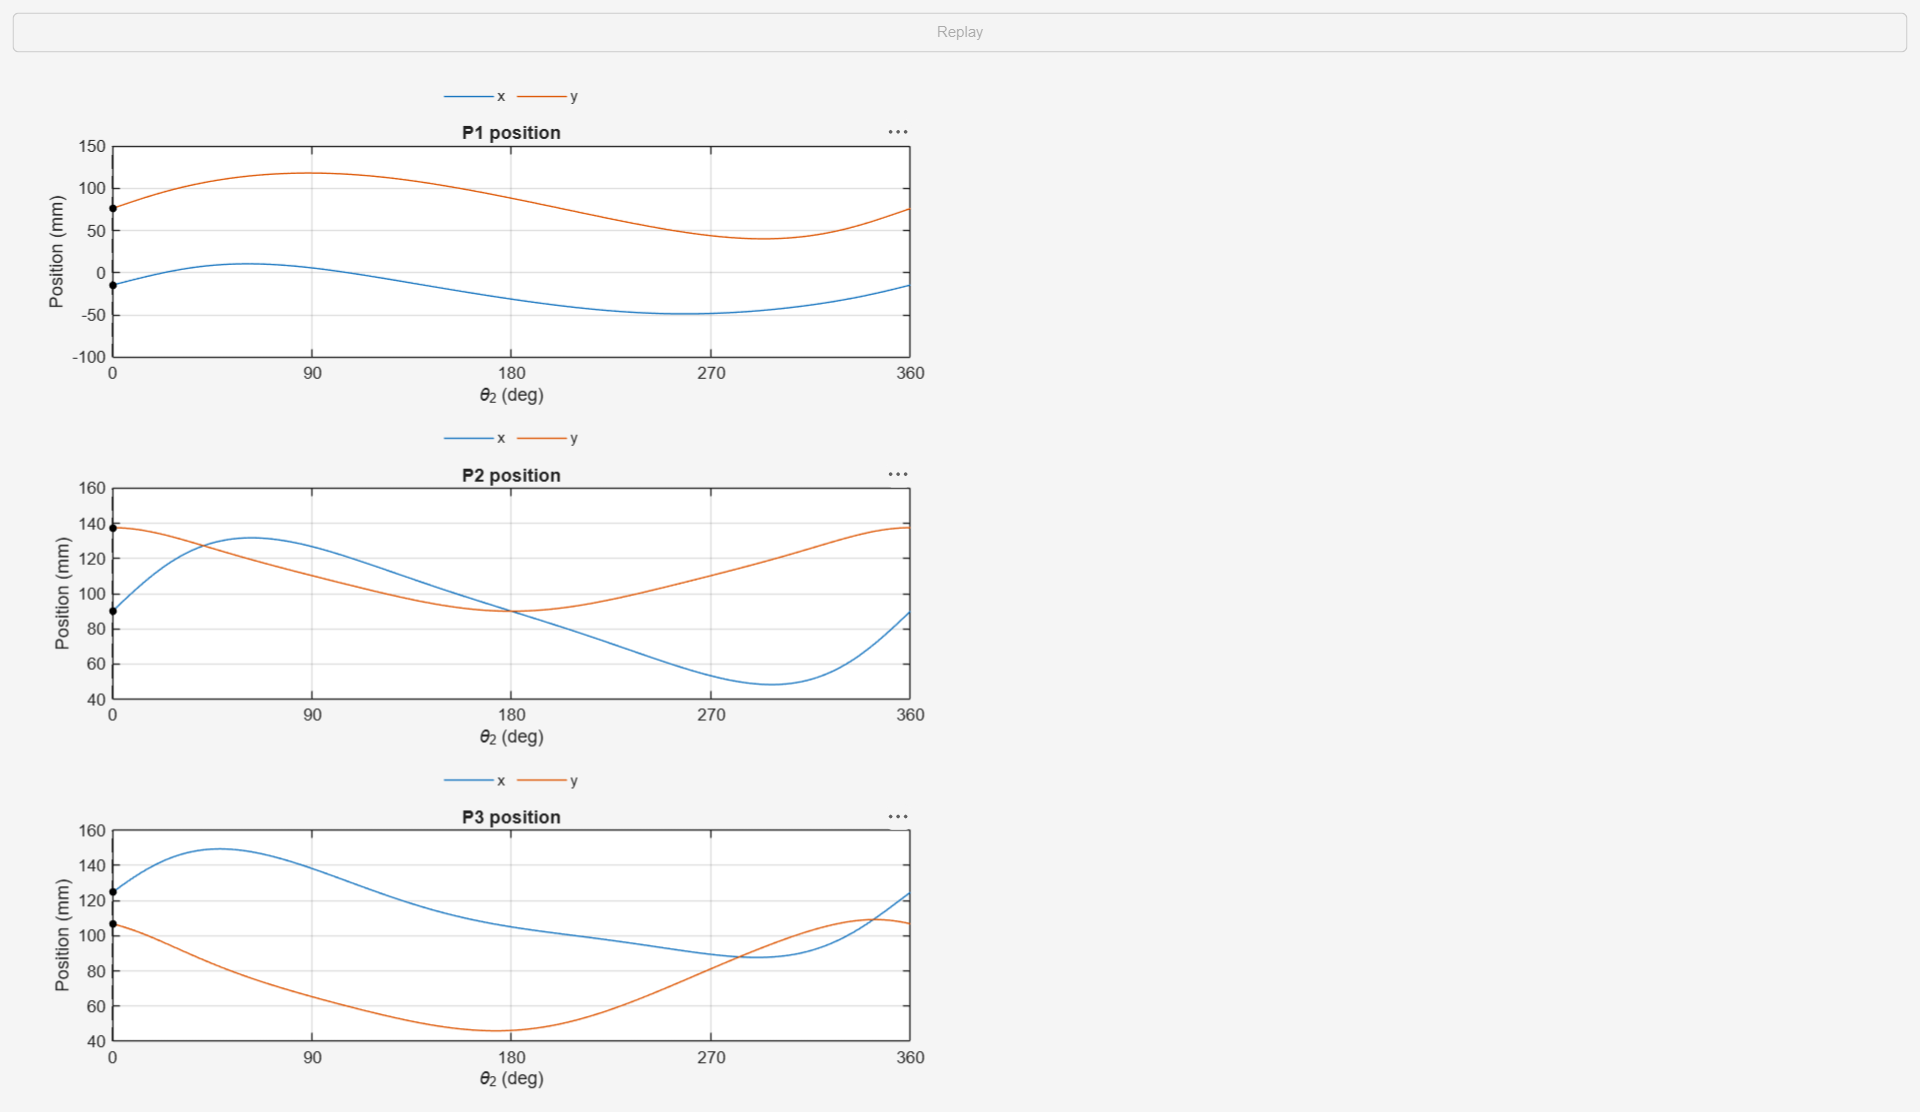

for k = 1:3
    nexttile(syncLayout,2*k-1);
    plot(theta2Deg,positionP(2*k-1:2*k,:)'); 
    grid on;
    title(sprintf('P%d position',k)); 
    xlabel('\theta_2 (deg)');
    ylabel('Position (mm)'); 
    legend('x','y','Location','northoutside','Orientation','horizontal','Box','off');
    hold on; 
    legend('AutoUpdate','off');
    fanimator(@(t) xline(rad2deg(t),'k--','LineWidth',1.1),'AnimationRange',[0 2*pi]);
    fanimator(@(t) plot(repmat(rad2deg(t),1,2),interp1(theta2Deg,positionP(2*k-1:2*k,:)',rad2deg(t)),'ko','MarkerFaceColor','k','MarkerSize',4),'AnimationRange',[0 2*pi]);
    hold off; 
    xlim([0 360]); xticks(0:90:360);

end

jointX = [Ax BxNew Px1 Px2 Px3]; 
jointY = [Ay ByNew Py1 Py2 Py3]; 
jointNames = {' A',' B',' P1',' P2',' P3'};
h_labels = @(t,k) text(double(subs(jointX(k),theta2,t)),double(subs(jointY(k),theta2,t)),jointNames{k},'FontWeight','bold','FontSize',9);

h_link2 = @(t) plot([O2x subs(Ax,t)],[O2y subs(Ay,t)],"-r");
h_link4 = @(t) plot([O4x subs(BxNew,t)],[O4y subs(ByNew,t)],"-g");
h_link3_1 = @(t) plot([subs(Ax,t) subs(BxNew,t) subs(Px1,t) subs(Ax,t)],...
                    [subs(Ay,t) subs(ByNew,t) subs(Py1,t) subs(Ay,t)],"-b");
h_link3_2 = @(t) plot([subs(Ax,t) subs(BxNew,t) subs(Px2,t) subs(Ax,t)],...
                    [subs(Ay,t) subs(ByNew,t) subs(Py2,t) subs(Ay,t)],"-b");
h_link3_3 = @(t) plot([subs(Ax,t) subs(BxNew,t) subs(Px3,t) subs(Ax,t)],...
                    [subs(Ay,t) subs(ByNew,t) subs(Py3,t) subs(Ay,t)],"-b");

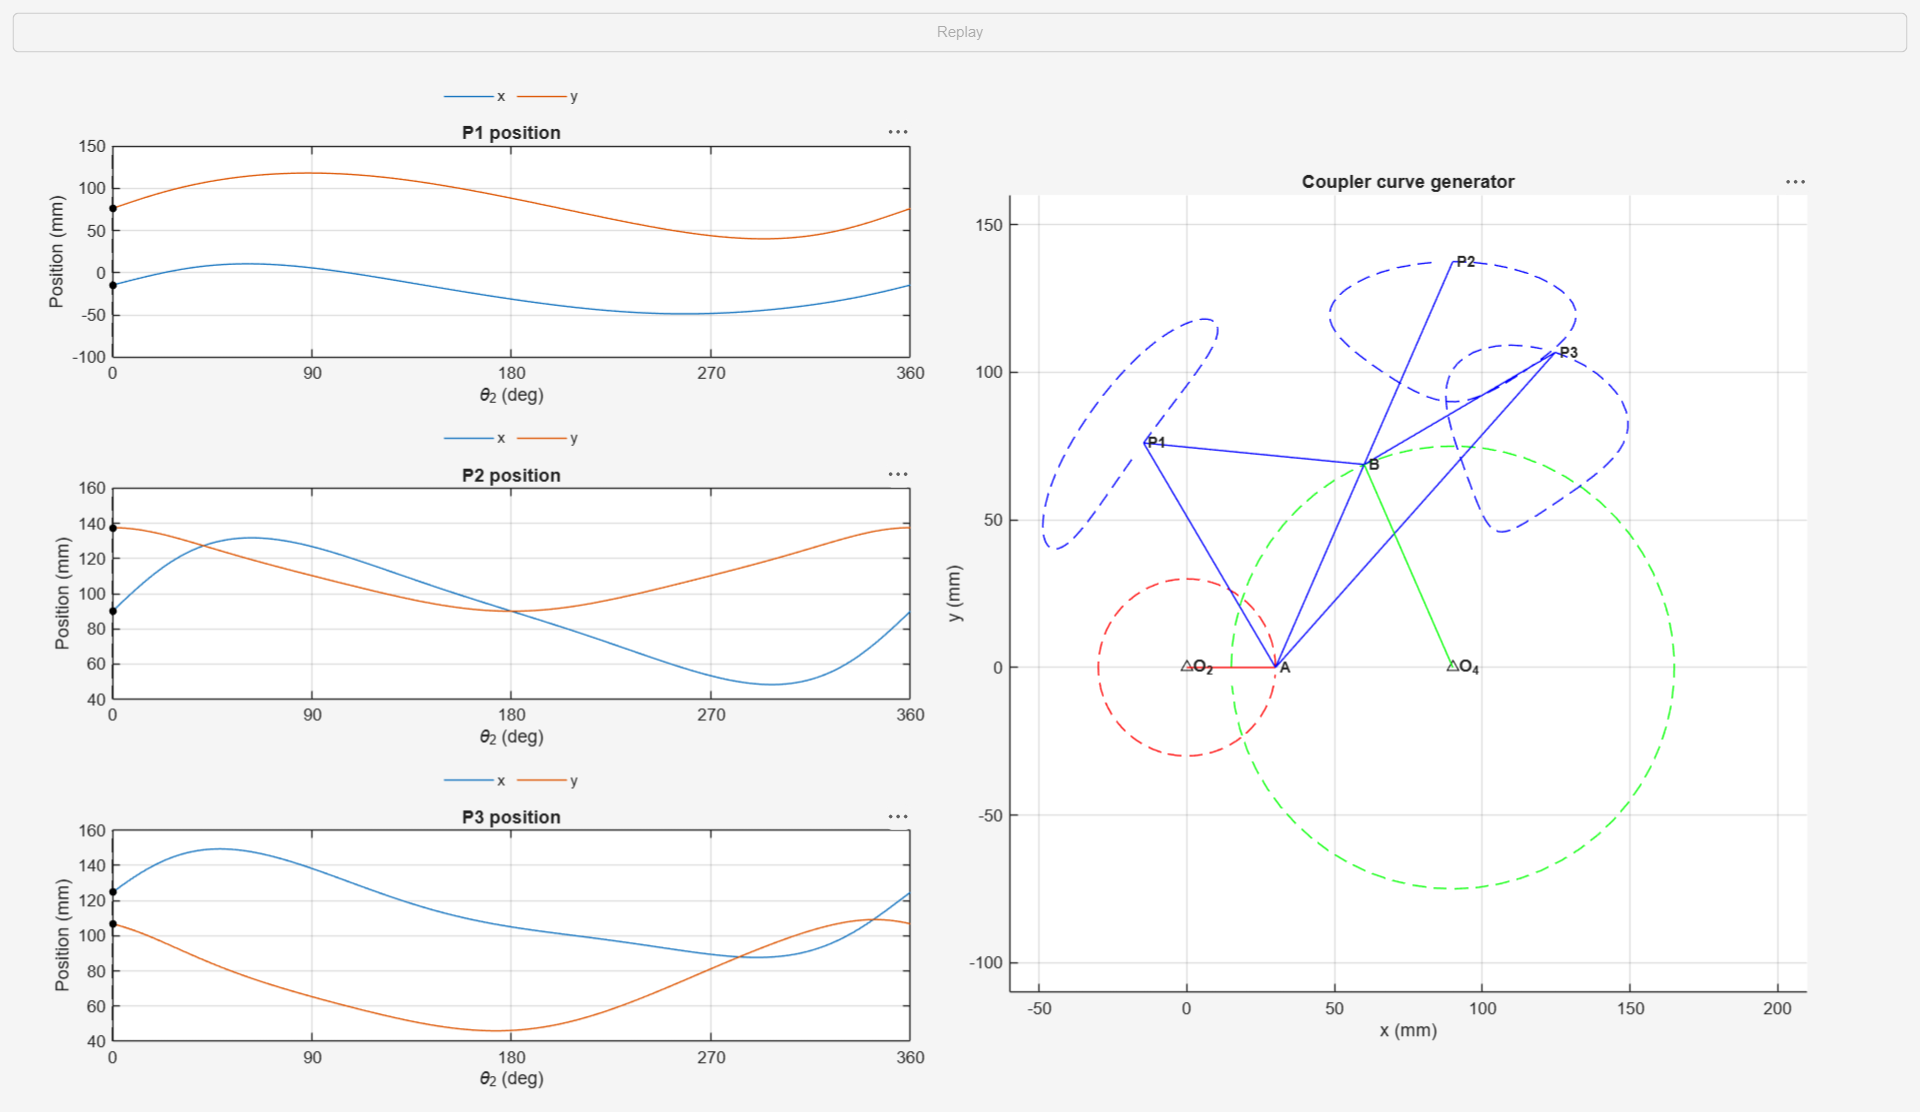

nexttile(syncLayout,2,[3 1]);
hold on
plot(O2x,O2y,"^k")
plot(O4x,O4y,"^k")
plot(subs(Ax,0:0.1:2*pi),subs(Ay,0:0.1:2*pi),"--r")
plot(subs(Bx,0:0.1:2*pi),subs(By,0:0.1:2*pi),"--g")
plot(subs(Px1,0:0.1:2*pi),subs(Py1,0:0.1:2*pi),"--b")
plot(subs(Px2,0:0.1:2*pi),subs(Py2,0:0.1:2*pi),"--b")
plot(subs(Px3,0:0.1:2*pi),subs(Py3,0:0.1:2*pi),"--b")

title('Coupler curve generator'); 
xlabel('x (mm)'); 
ylabel('y (mm)'); 
grid on; 
text([O2x O4x],[O2y O4y],{' O_2',' O_4'},'FontWeight','bold');
for k = 1:5
    fanimator(@(t) h_labels(t,k)); 
end
fanimator(h_link2)
fanimator(h_link3_1)
fanimator(h_link3_2)
fanimator(h_link3_3)
fanimator(h_link4)
hold off
axis image;
xlim(xlim + [-10 10]); ylim(ylim + [-10 10]);

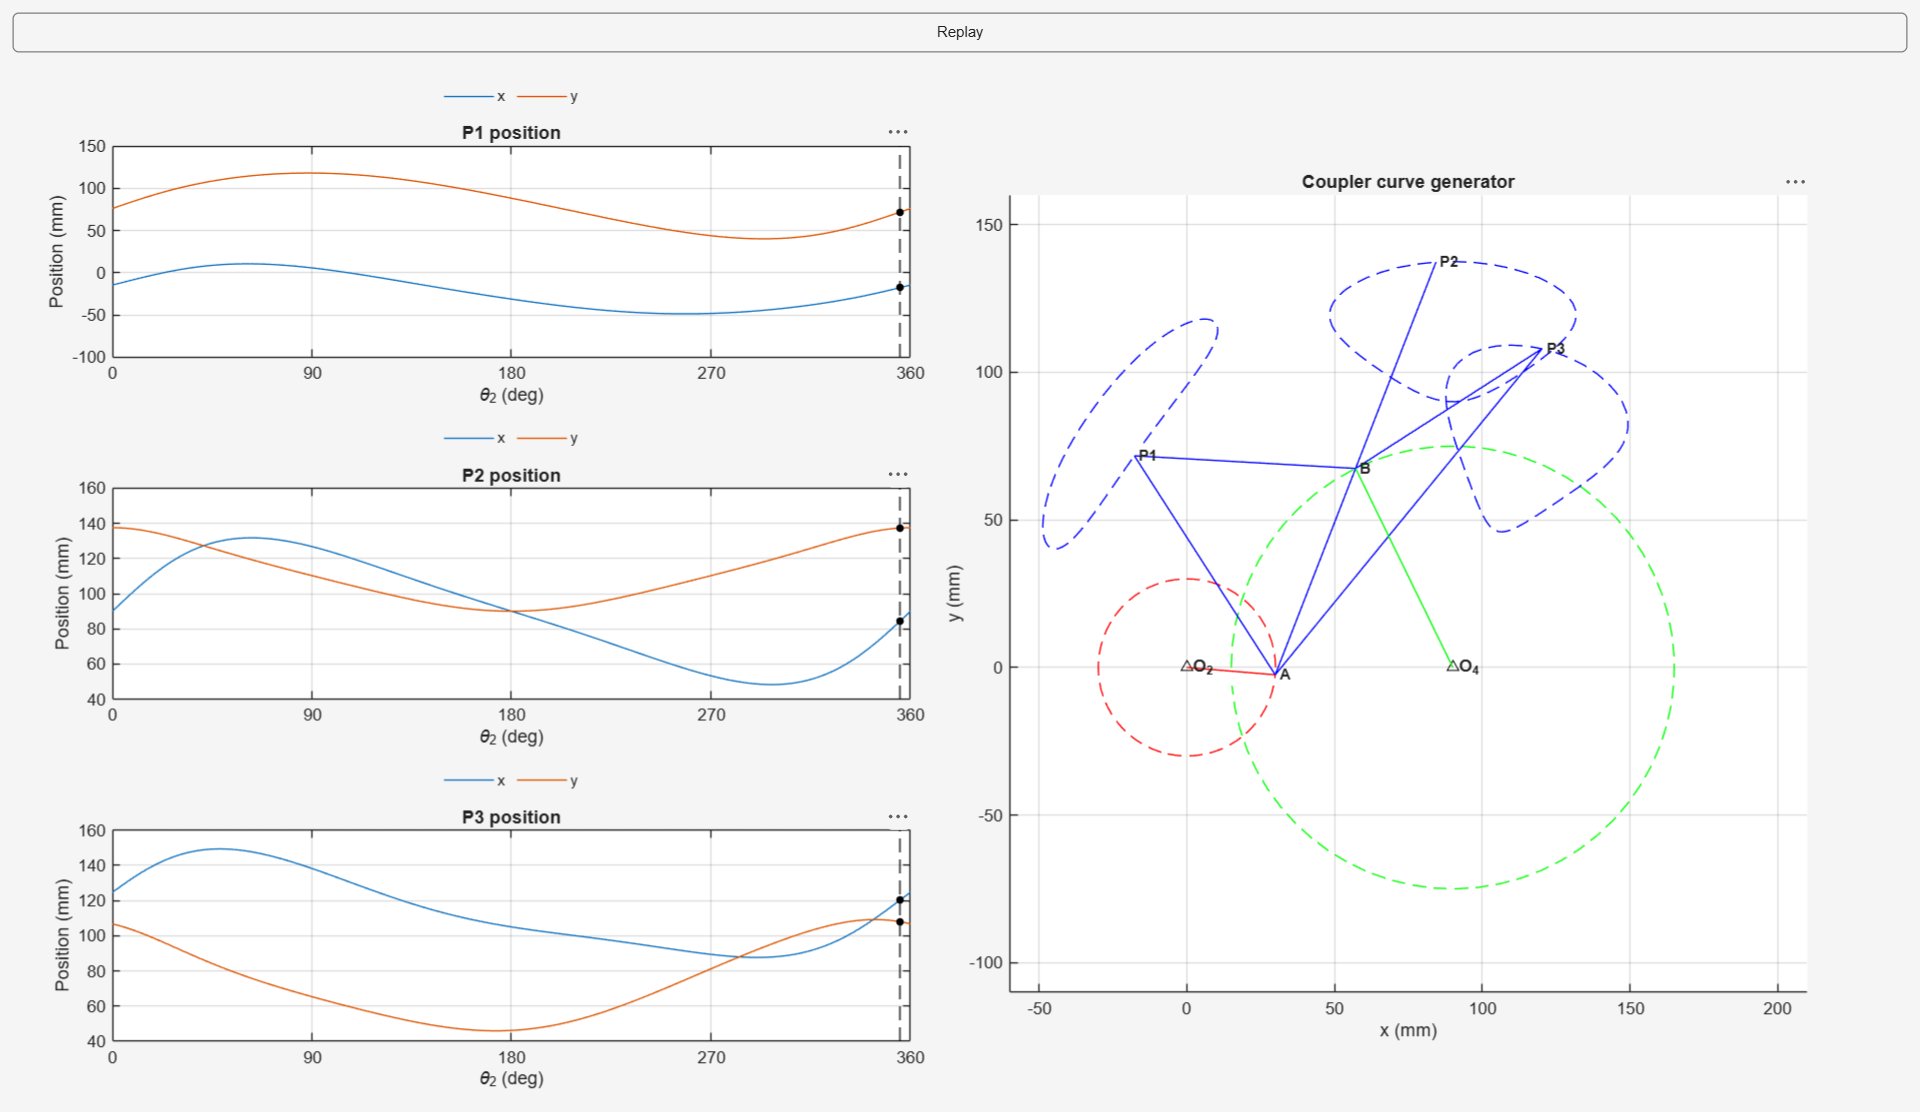

replayButton.ButtonPushedFcn = @(button,~) replayCoupler(button,syncFigure,omega2);
replayCoupler(replayButton,syncFigure,omega2);

function replayCoupler(button,fig,crankSpeed)
    button.Enable = 'off';
    playAnimation(fig,'AnimationRange',[0 2*pi],'SpeedFactor',crankSpeed);
    if isvalid(button)
        button.Enable = 'on';
    end
end


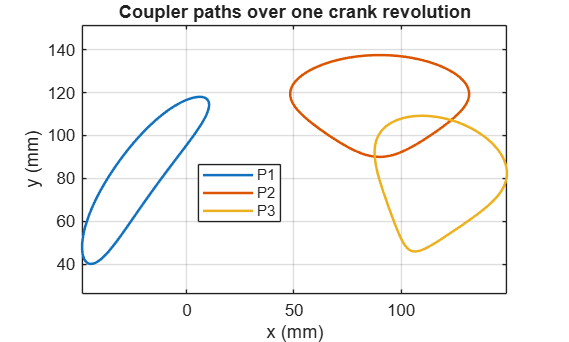

figure;
plot(positionP(1:2:5,:)',positionP(2:2:6,:)','LineWidth',1.5);
axis equal; grid on;
xlabel('x (mm)'); ylabel('y (mm)');
legend('P1','P2','P3','Location','best');
title('Coupler paths over one crank revolution');